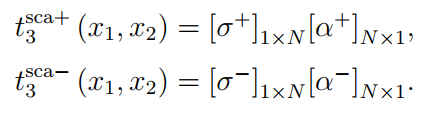


$$t_3^{\textrm{sca}+} \left(x_1 ,x_2 \right)=\left({\left\lbrack \sigma_{31}^+ \right\rbrack }_{1\times N} +{\left\lbrack \sigma_{33}^+ \right\rbrack }_{1\times N} \right){\left\lbrack \alpha^+ \right\rbrack }_{N\times 1}$$



$$t_3^{\textrm{sca}-} \left(x_1 ,x_2 \right)=\left({\left\lbrack \sigma_{31}^- \right\rbrack }_{1\times N} +{\left\lbrack \sigma_{33}^- \right\rbrack }_{1\times N} \right){\left\lbrack \alpha^- \right\rbrack }_{N\times 1}$$


% clc; clear;

% FEM SH wave %

% Input %

% density:matterial parameter %

% h:unit length of x3 direction %

% mu:shear modulus %

% Cf:cicular frequency %

density1=2.7*10^3;
density2=7.8*10^3;
mu1=26.1*10^9;
mu2=79*10^9;
h=1;
he = 0.5*10^(-3); % 归一化缩放因子
f=4.1*10^6;
Cf = 2*pi*f;
mode_in = 2;

% Geometry Setting %

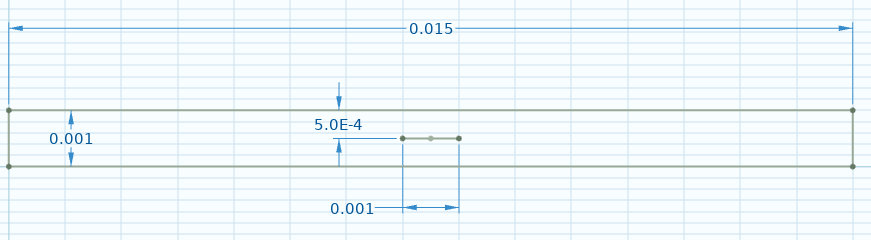

L=1.5*10^(-2);
W=1*10^(-3);
L_crack = W;

% Import Mesh Information %

% bnd_401是左边界节点编号，bnd_501是右边界，bnd_101是自由应力边界（上下边界及缺陷边界） %

% [Nnode, Nelement, Coordinate, Ielement, bnd_401, bnd_501, bnd_101, bnd_401_e, bnd_501_e, bnd_101_e, dL, dW] = read_mesh_info(L, W);

[Nnode, Nelement, Coordinate, Ielement, dL, dW] = read_mesh_info();
[bnd_401, bnd_501, bnd_101, bnd_401_e, bnd_501_e, bnd_101_e] = bound_information(Coordinate, Ielement,L,W,L_crack);

Nelement_crack = round(L_crack/dL);
Nnode_crack = 2*Nelement_crack-1;

L_ele = round(L/dL);
L_nod_s = 2*L_ele+1;
L_nod_d = L_ele+1;

% 坐标缩放
Coordinate = Coordinate/he;

% Stiffness matrix %
% ngq:integration points, total integration points is 8*8 %
% xgq:si or ti, wgq:wi or wj %
% K: global stiffness matrix %
% M: global mass matrix %
% Ke: local stiffness matrix, Me: local Mass matrix % 
[ Kg,K,M ] = Stiffness_Mass_matrix( Nnode,Nelement,Ielement,Coordinate,mu1,mu2,h,density1,density2,he,Cf );
Kg_o = Kg;
% SH dispersion 
CT1 = sqrt(mu1/density1);
CT2 = sqrt(mu2/density2);
[ root,root_d,zamp_mode,Amp ] = SH_dispersion( mu1,mu2,density1,density2,f,he );

% Traction_Known_R (-Kg*U_in+t_401_in+t_501_in)
[ F,U_in ] = Traction_Known_R( Nnode,mode_in,f,CT1,CT2,he,Coordinate,Ielement,root,Kg,W,dW,dL,L_nod_s,L_nod_d,Amp,bnd_401_e,bnd_501_e,mu1,mu2 );

% UnKnown Traction (left hand side)
[ Kg,zint_inv ] = Traction_scatter_401_501( bnd_401,bnd_501,bnd_401_e,bnd_501_e,root,f,CT1,CT2,he,mu1,mu2,Coordinate,Ielement,dW,Amp,Kg );

U_sc = Kg\F;

for i = 1:size(bnd_401,2)
    indx_n = bnd_401(1,i);
    Usc_401(i,1)= U_sc(indx_n,1);
end

for i = 1:size(bnd_501,2)
    indx_n = bnd_501(1,i);
    Usc_501(i,1)= U_sc(indx_n,1);
end

% Re,Tr,eng_R,eng_T
n_mode_max = size(root,2);
[ Re,Tr,eng_R,eng_T ] = Co_Eng_RaT( n_mode_max,mode_in,bnd_401_e,bnd_501_e,Coordinate,Ielement,root,f,CT1,CT2,mu1,mu2,he,dW,Amp,zint_inv,U_sc );